BRW_st.name='BRW';
BRW_st.lat=71.32;
BRW_st.lon=-156.6;
BRW_st.alt=11;
BRW_st.env='P';
BRW_st.footp='P';


BRW_rd2=read_betsy('BRW_1976_2018',BRW_st.name);

a =   232.4701  174.2103  177.3607  199.6996  213.9565  213.4015  213.4770  213.9173  212.6799  212.7551  443.7211  230.8866  443.7211  214.9256  214.3878  214.4638  214.9256  213.6430  213.7187  448.3494  232.6273  448.3494

BRW_rd=read_betsy('BRW_1976_2018_longformat',BRW_st.name);

datevec(BRW_rd.Time(1))

ans =         1976           5           8           0           0           0

datevec(BRW_rd.Time(end))

ans =         2019           1           1           0           0           0

prctile(BRW_rd.U_S,[5 50 95])

ans =          0    7.3000   26.3000

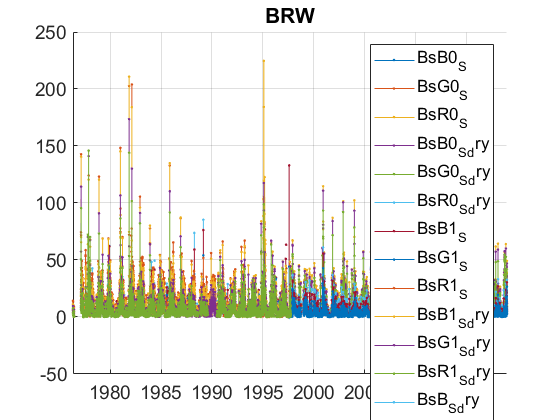

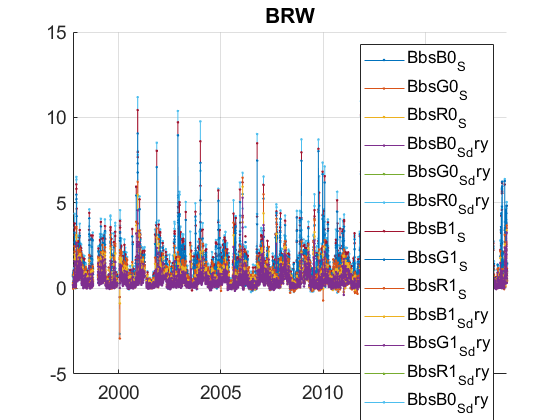

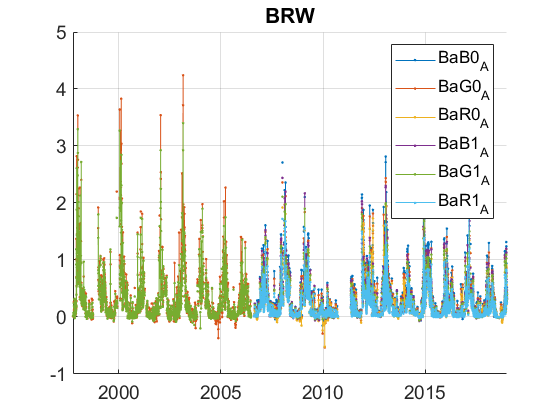

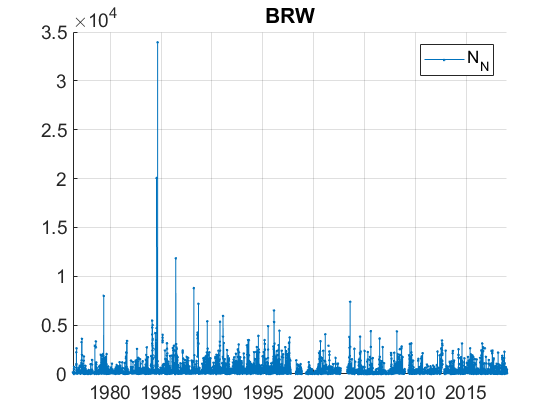

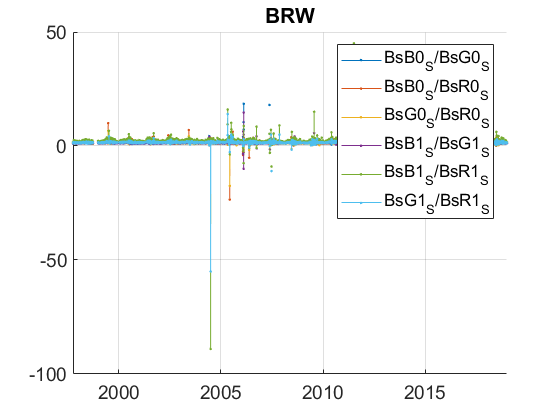

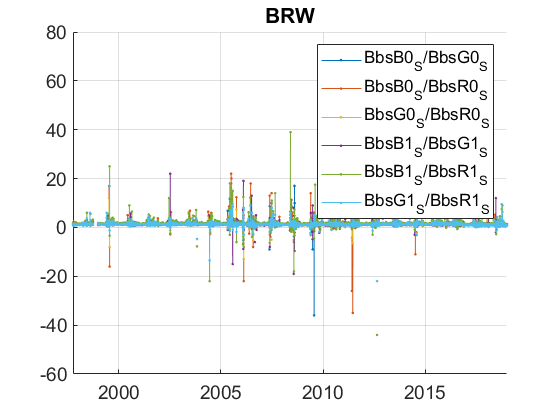

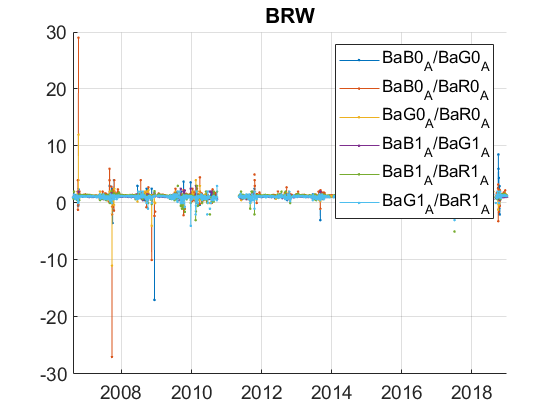

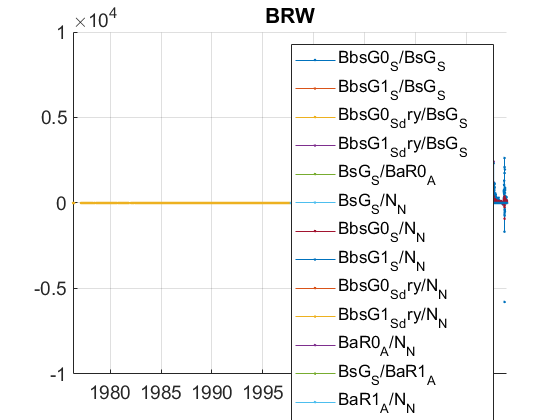

plotFigControl(BRW_rd,BRW_st.name);

% 2 size cut, ok
% sc: ok, max in spring, some negatives
% abs: 2 size cut, max in spring, some negatives
%Clear seasonal cycle in BbsF with max in summer
%clear seasonal cycle in SSA with max in autumn


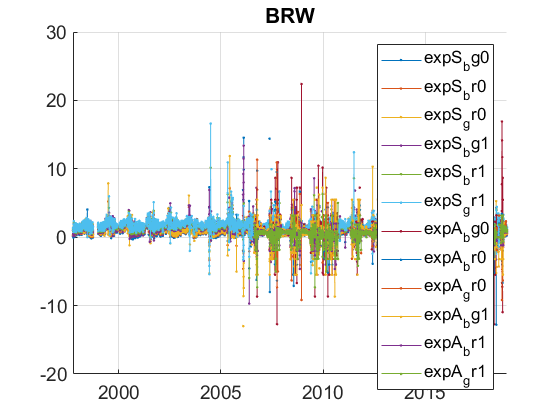

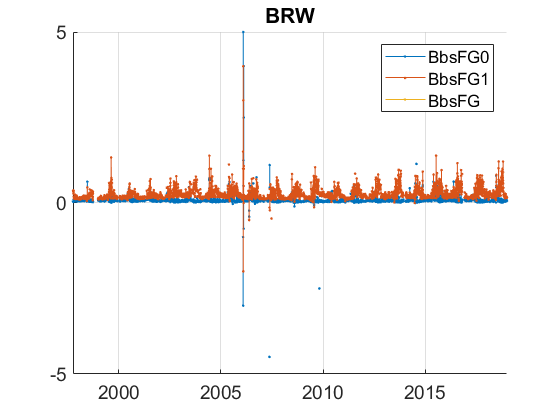

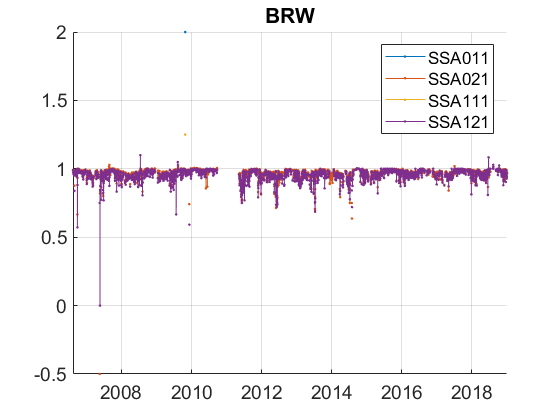

lambdaSC=[450;550;700]*ones(1,4);
lambdaAE=[467;530;660]*ones(1,4);
lambdaAE7=[370 470 520 590 660 880 950];
BRW_cal=compute_exp_SSA(BRW_rd,lambdaSC, lambdaAE);
plotFigControl_cal(BRW_cal,BRW_st.name);

%Questions:
%problems:
%scat: b:no data from 1993-1997, but data for g,r and Q. What is Q ?
%scat: too high values in spring 1995: what happened ?
%scat: greatest "spikes" for radiance than for TSI
% otherwise the green seems to be homogeneous.

%backscatter: why no data before 1998 ? MRP: no backscat
%backscat: some issue with the red wavelength since 2017: ratio G/R and B/R are lower.
%Backscat :negatives only between 2005 and 2010 and more low values between 2006 and 2015. Also visible in the ratio between parameters

%BbsF: not similar seasonality between PM10 and PM1: PM1 seems to have a different seasonality in 2003-2006 and 2008- with longer season with high values.

%abs: strange low values in 2010-2011: bad data ? also visible on SSA.
% abs: the ratio between the wavelength == 1, 1.5 and 2 are favored: this is very strange. Do you have an explanation?
%abs: similarly the exp=0 0.83 1.31 ... 2 as well as -2 are favored.
%abs: for the green, it seems to be homogeneous between PSAP 1w,PSAP 3w and CLAP
%abs: I don't have the AE 31 from 2010 to 2018 (not sure it is necessary).

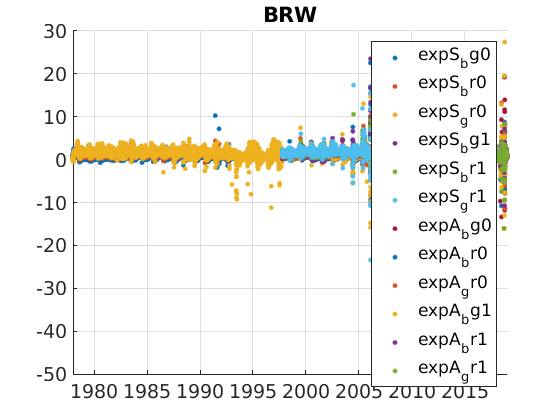

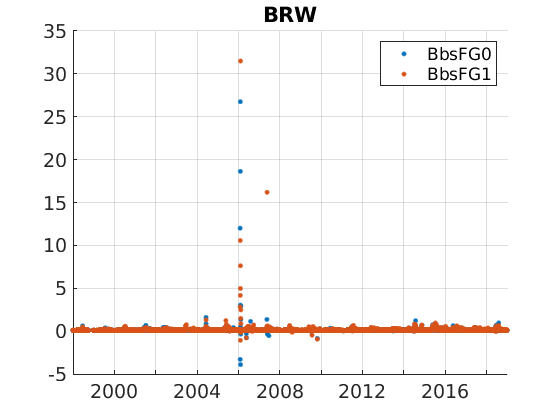

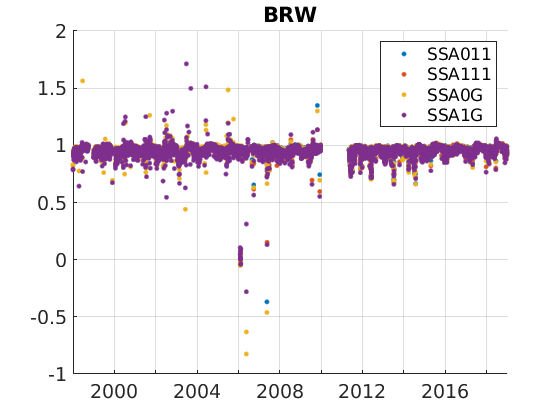

BRW_tr=BRW_rd;
BRW_tr.y=year(BRW_tr.Time);
% begin at the beginning of a year: scat 1978 abs + backscat + SSA: 1998
% end 2018
P=timerange('1978-01-01','2019-01-01');
BRW_tr=BRW_tr(P,:);

% %U >50% for only few cases --> no trend in U and dry
names=fieldnames(BRW_tr);
c= startsWith(names,["T1";"T0";"T_";"P_";"P1_";"P0_";"N";"Uu";"U1"]) | endsWith(names,'dry') | contains(names,'Q');
N=names(c);
for i=1:length(N)
    BRW_tr.(N{i})=[];
end
%BsB_S: problem from 5.4.1993 to october 1997: to invalidate
Px=timerange('1993-04-05','1997-10-01');
BRW_tr.BsB_S11(Px)=NaN;
%one time series for TSP and PM10
Pold=timerange('1978-01-01','1997-10-01');
BRW_tr.BsB0_S11(Pold)=BRW_tr.BsB_S11(Pold);
BRW_tr.BsG0_S11(Pold)=BRW_tr.BsG_S11(Pold);
BRW_tr.BsR0_S11(Pold)=BRW_tr.BsR_S11(Pold);
BRW_tr.U0_S11(Pold)=BRW_tr.U_S11(Pold);
BRW_tr.BsB_S11=[];
BRW_tr.BsG_S11=[];
BRW_tr.BsR_S11=[];
BRW_tr.U_S11=[];
%backscat and abs: 1998-2018 
P2=timerange('1997-10-01','1998-01-01');
BRW_tr.BbsG0_S11(P2)=NaN;
BRW_tr.BbsG1_S11(P2)=NaN;
BRW_tr.BbsB0_S11=[];
BRW_tr.BbsR0_S11=[];
BRW_tr.BbsB1_S11=[];
BRW_tr.BbsR1_S11=[];
%Abs:
BRW_tr.BaG0_A11(P2)=NaN;
BRW_tr.BaG1_A11(P2)=NaN;
BRW_tr.BaB0_A11(P2)=NaN;
BRW_tr.BaB1_A11(P2)=NaN;
BRW_tr.BaR0_A11(P2)=NaN;
BRW_tr.BaR1_A11(P2)=NaN;
%abs: invalidate 25.12.2009 to jan 2011 (end story leak)
P3=timerange('2009-12-25','2011-01-01');
BRW_tr.BaG0_A11(P3)=NaN;
BRW_tr.BaG1_A11(P3)=NaN;
BRW_tr.BaB0_A11(P3)=NaN;
BRW_tr.BaB1_A11(P3)=NaN;
BRW_tr.BaR0_A11(P3)=NaN;
BRW_tr.BaR1_A11(P3)=NaN;
% BRW_tr.BaB0_A11=[];
% BRW_tr.BaR0_A11=[];
% BRW_tr.BaB0_A11=[];
% BRW_tr.BaR0_A11=[];
%compute new values
BRW_cal2=compute_exp_SSA(BRW_tr,lambdaSC, lambdaAE);
% absG is longer than absR --> compute SSA with green scat and abs
BRW_cal2.SSA0G=BRW_tr.BsG0_S11./(BRW_tr.BsG0_S11+BRW_tr.BaG0_A11);
BRW_cal2.SSA1G=BRW_tr.BsG1_S11./(BRW_tr.BsG1_S11+BRW_tr.BaG1_A11);
plotFigControl_cal(BRW_cal2,BRW_st.name);

BRW_tr=outerjoin(BRW_tr, BRW_cal2);

%compute abs and SSA trends only on G, the longest time series
BRW_tr.BaB0_A11=[];
BRW_tr.BaB1_A11=[];
BRW_tr.BaR0_A11=[];
BRW_tr.BaR1_A11=[];
BRW_tr.SSA011=[];
BRW_tr.SSA111=[];
%compute expA exponent only on BG and only since 1.1.2007 (whole year)
Pexp=timerange('2006-01-01','2007-01-01');
BRW_tr.expA_bg0(Pexp)=NaN;
BRW_tr.expA_bg1(Pexp)=NaN;
BRW_tr.expA_br0=[];
BRW_tr.expA_br1=[];
BRW_tr.expA_gr0=[];
BRW_tr.expA_gr1=[];

BRW_result= all_trend_STN(BRW_tr,BRW_st); 
plot_10y_in_two(BRW_result,BRW_st);

BRW_result_D=BRW_result;